downs = grabFromFilter('Downs');
ups = grabFromFilter('Ups');

%parse the data to store the responses from every cell for every epoch
%organized by stimulus orientation.
allOrientations = [0:45:315];

upVals = zeros(size(ups, 1), 8); %will hold mean responses of each cell for each stimulus direction
downVals = zeros(size(downs, 1), 8);

upAllSpikesByCell  = cell(8, 2); %will hold # of spikes for all epochs for each cell organized by stimulus orientation
upAllSpikesByCell(:, 1) = num2cell(allOrientations');

downAllSpikesByCell  = cell(8, 2);
downAllSpikesByCell(:, 1) = num2cell(allOrientations');

upAllSpikesByOrientation = cell(8, 1);
downAllSpikesByOrientation = cell(8, 1);

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'; 'Moving_Grating_Direction'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'SP10'; 'Extracellular'}; %child field name should be one of these. Priority is in given order'
mustHave_1 = [];
mustHave_2 = {'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

%grab data for up cells
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    orientations = loc.Analysis_Results.Orientation;
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    spikesByOrientation = loc.Analysis_Results.spikesByOrientation;
    
    for j = 1:numel(orientations)
        o_j = orientations(j);
        upVals(i, allOrientations == o_j) = spikes(j);
    end
    upVals(i, :) = upVals(i, :)/max(upVals(i, :)); %normalize
    
    maxFR = 0;
    for j = 1:size(spikesByOrientation, 1)
        rates = spikesByOrientation{j, 2};
        maxFR = max([maxFR, rates]);
    end
    
    for j = 1:numel(orientations)
        slot_j = allOrientations == orientations(j);
        o_j = upAllSpikesByCell{slot_j, 2}; %pull out the cell array inside the cell array that holds total spikes for each epoch for each cell
        normedspikes_j = spikesByOrientation{j, 2}./maxFR;
        o_j{end+1, 1} = normedspikes_j; %insert total spikes for this cell for each epoch at that orientation
        upAllSpikesByCell{slot_j, 2} = o_j; %put o_j back into the bigger cell array
        
        %also store spikes in an array that groups everything together
        %based on orientation but not by cell
        upAllSpikesByOrientation{slot_j} = [upAllSpikesByOrientation{slot_j} normedspikes_j];
    end

end
upMean = mean(upVals); %population tuning curve

%grab data for down cells
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    orientations = loc.Analysis_Results.Orientation;
    spikes = loc.Analysis_Results.mean_spikesByOrientation;
    spikesByOrientation = loc.Analysis_Results.spikesByOrientation;

    for j = 1:numel(orientations)
        o_j = orientations(j);
        downVals(i, allOrientations == o_j) = spikes(j);
    end
    downVals(i, :) = downVals(i, :)/max(downVals(i, :));
  
    maxFR = 0;
    for j = 1:size(spikesByOrientation, 1)
        rates = spikesByOrientation{j, 2};
        maxFR = max([maxFR, rates]);
    end
    
    for j = 1:numel(orientations)
        slot_j = allOrientations == orientations(j);
        o_j = downAllSpikesByCell{slot_j, 2}; %pull out the cell array inside the cell array that holds total spikes for each epoch for each cell
        normedspikes_j = spikesByOrientation{j, 2}./maxFR;
        o_j{end+1, 1} = normedspikes_j; %insert total spikes for this cell for each epoch at that orientation
        downAllSpikesByCell{slot_j, 2} = o_j; %put o_j back into the bigger cell array
        
        %also store spikes in an array that groups everything together
        %based on orientation but not by cell
        downAllSpikesByOrientation{slot_j} = [downAllSpikesByOrientation{slot_j} normedspikes_j];
    end
end
downMean = mean(downVals);


Response Models

Decoding models will be built on simulated ON DS responses. In order to simulate the responses of UP and DOWN cells to any given stimulus, I will first build probability distributions that describe the probability of each cell type to produce a certain response, given a stimulus. Specifically, I am using a smooth kernel method to fit respohse distributions of the responses of UP and DOWN cells to a bar moving in each of 8 directions. This provides a description of P(R|S).

The below plots are the fit distributions of P(R|S) for 8 different directions. These plots are the cumulative P(R|S) generated directly from empirical data for both UP and DOWN cells. Responses are normalized to the maximum response for the cell. Curve color denotes stimulus angle with darker colors indicating angles that are closer to the preferred direction of the cell. Notice the difference in spread between UP and DOWN cell CDF curves across angles - this is a function of the different tuning widths of UP and DOWN cells.

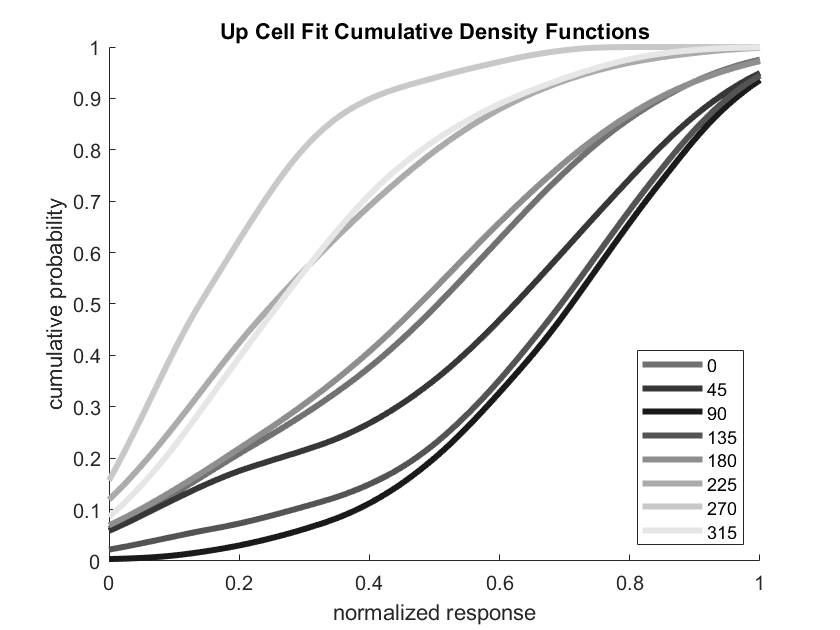

upDistributionFits = zeros(8, 100); %will hold the fitted values of a cdf for each of 8 stimulus directions for up cells
downDistributionFits = zeros(8, 100);
xFills = linspace(0, 1, 100);
for i = 1:numel(allOrientations)
    distribution_iUp = upAllSpikesByOrientation{i};
    pd = fitdist(distribution_iUp','Kernel','Kernel','epanechnikov');
    y = cdf(pd, xFills);
    upDistributionFits(i, :)= y;
    
    distribution_iDown = downAllSpikesByOrientation{i};
    pd = fitdist(distribution_iDown','Kernel','Kernel','epanechnikov');
    y = cdf(pd, xFills);
    downDistributionFits(i, :)= y;
end

colorWeights = linspace(0.1, 0.9, 8)';
colors = repmat(colorWeights, 1, 3);

colorsB = colors([ 4,2,1,3,5 ,6 ,7 ,8], :);
figure
title('Up Cell Fit Cumulative Density Functions')
hold on
plot(xFills, upDistributionFits, 'LineWidth', 3)
lgd = legend('0', '45', '90', '135', '180', '225', '270', '315');
lgd.Location = 'southeast';
xlabel('normalized response')
ylabel('cumulative probability')
colororder(colorsB)
hold off

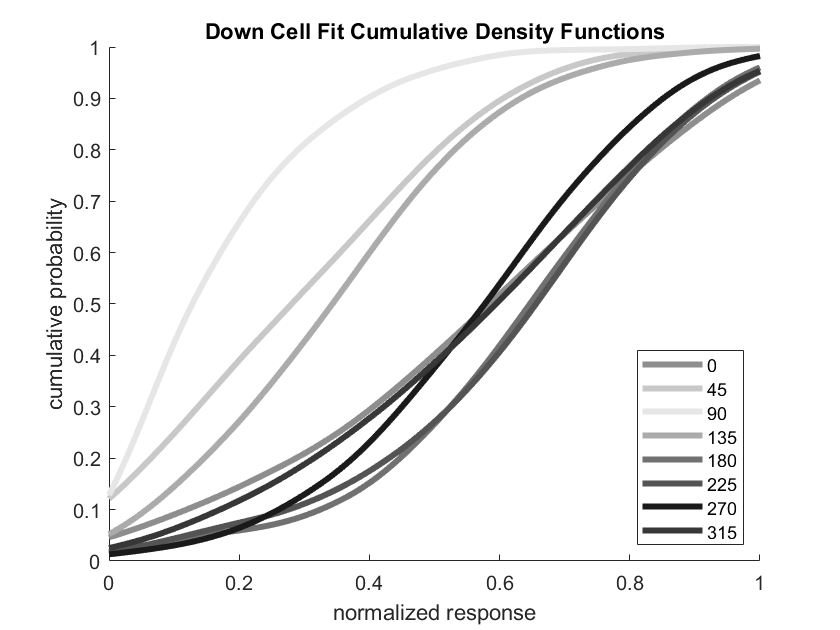

colorsM = colors([ 5,7,8,6,4 ,3 ,1 ,2], :);
%colorsM = repmat([1 0 1], 8, 1).*colorsM;

figure
title('Down Cell Fit Cumulative Density Functions')
hold on
plot(xFills, downDistributionFits, 'LineWidth', 3)
lgd = legend('0', '45', '90', '135', '180', '225', '270', '315');
lgd.Location = 'southeast';
xlabel('normalized response')
ylabel('cumulative probability')
colororder(colorsM)
hold off

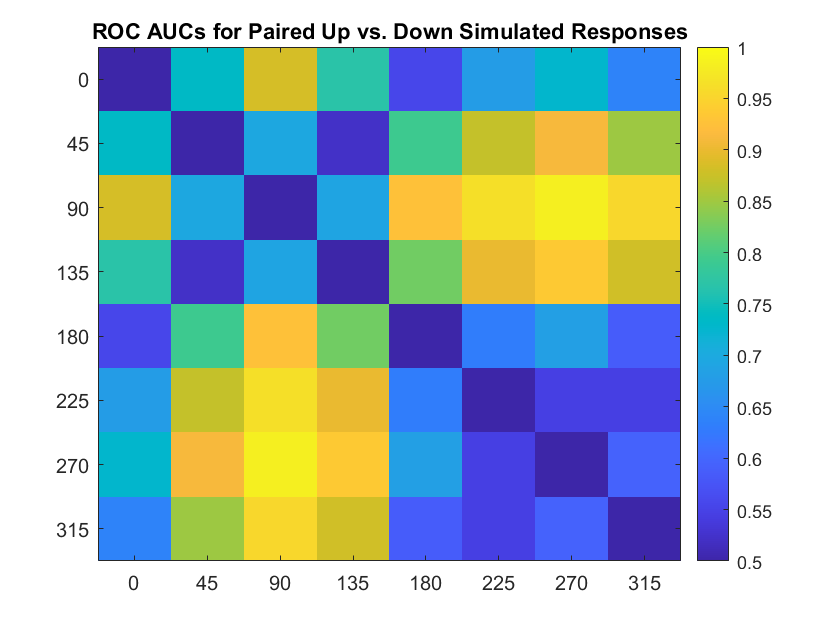



n = 10000; %number of simulations to run for each direction
simulatedDifferences = zeros(numel(allOrientations), n);
for i = 1:numel(allOrientations)
    simulationDirection_i = allOrientations(i);
    cdfUp = upDistributionFits(i, :);
    cdfDown = downDistributionFits(i, :);
    
    upSeeds = rand(1, n);
    downSeeds = rand(1, n);
    
    upResponses = zeros(1, n);
    downResponses = zeros(1, n);
    for run = 1:n
        [~, indxUp] = min((cdfUp - upSeeds(run)).^2);
        [~, indxDown] = min((cdfDown - downSeeds(run)).^2);
        
        upResponses(run) = xFills(indxUp);
        downResponses(run) = xFills(indxDown);
    end
    simulatedDifferences(i, :) = upResponses - downResponses;
end




%build discriminability matrix
AUC_matrix = zeros(numel(allOrientations));
for i = 1:numel(allOrientations)
    distribution_1 = simulatedDifferences(i, :);
    for j = 1:numel(allOrientations)
        distribution_2 = simulatedDifferences(j, :);
        
        labels =  [zeros(1, numel(distribution_1)), ones(1, numel(distribution_2))];
        scores = [distribution_1, distribution_2];
        [~, ~, ~, AUC] = perfcurve(labels, scores, 1);
        AUCNorm = max([AUC, 1-AUC]);
        
        AUC_matrix(i, j) = AUCNorm;
    end
end

figure
imagesc(AUC_matrix)
hold on
title('ROC AUCs for Paired Up vs. Down Simulated Responses')
ts = {'0', '45', '90', '135', '180', '225', '270', '315'};
xticklabels(ts)
yticklabels(ts)
colorbar()
caxis([0.5 1])

Symmetry

Next, I repeat the same approach, but replace the DOWN cells with a flipped version of the UP cells. This creates a scenario in which stimuli are encoded by two symmetric populations of DS cells that have preferred directions which are 180 degrees apart.

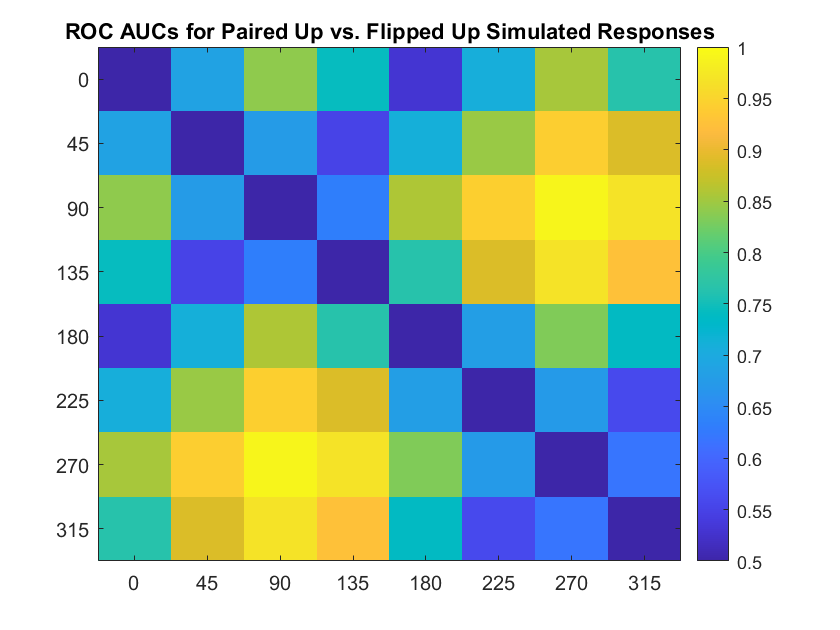


simulatedDifferences_UPFLIPPED = zeros(numel(allOrientations), n);
upDistributionFits_FLIPPED = upDistributionFits([5:8, 1:4], :);

for i = 1:numel(allOrientations)
    simulationDirection_i = allOrientations(i);
    cdfUp = upDistributionFits(i, :);
    cdfUp_FLIPPED = upDistributionFits_FLIPPED(i, :);
    
    upSeeds = rand(1, n);
    upFLIPPEDSeeds = rand(1, n);
    
    upResponses = zeros(1, n);
    upFLIPPEDResponses = zeros(1, n);
    for run = 1:n
        [~, indxUp] = min((cdfUp - upSeeds(run)).^2);
        [~, indxDown] = min((cdfUp_FLIPPED - upFLIPPEDSeeds(run)).^2);
        
        upResponses(run) = xFills(indxUp);
        upFLIPPEDResponses(run) = xFills(indxDown);
    end
    simulatedDifferences_UPFLIPPED(i, :) = upResponses - upFLIPPEDResponses;
end

%build discriminability matrix
AUC_matrix_UPFLIPPED = zeros(numel(allOrientations));
for i = 1:numel(allOrientations)
    distribution_1 = simulatedDifferences_UPFLIPPED(i, :);
    for j = 1:numel(allOrientations)
        distribution_2 = simulatedDifferences_UPFLIPPED(j, :);
        
        labels =  [zeros(1, numel(distribution_1)), ones(1, numel(distribution_2))];
        scores = [distribution_1, distribution_2];
        [~, ~, ~, AUC] = perfcurve(labels, scores, 1);
        AUCNorm = max([AUC, 1-AUC]);
        
        AUC_matrix_UPFLIPPED(i, j) = AUCNorm;
    end
end

figure
imagesc(AUC_matrix_UPFLIPPED)
hold on
title('ROC AUCs for Paired Up vs. Flipped Up Simulated Responses')
ts = {'0', '45', '90', '135', '180', '225', '270', '315'};
xticklabels(ts)
yticklabels(ts)
colorbar()
caxis([0.5 1])

The following two matrices highlight the difference between the symmetric and asymmetric cases. The first shows the element-wise difference in AUC values where negative values correspond to a higher AUC in the symmetric case than in the asymmetric case. The second shows the percent change in AUC value. Again, a negative value indicates that the asymmetric case has a lower AUC than the symmetric case.

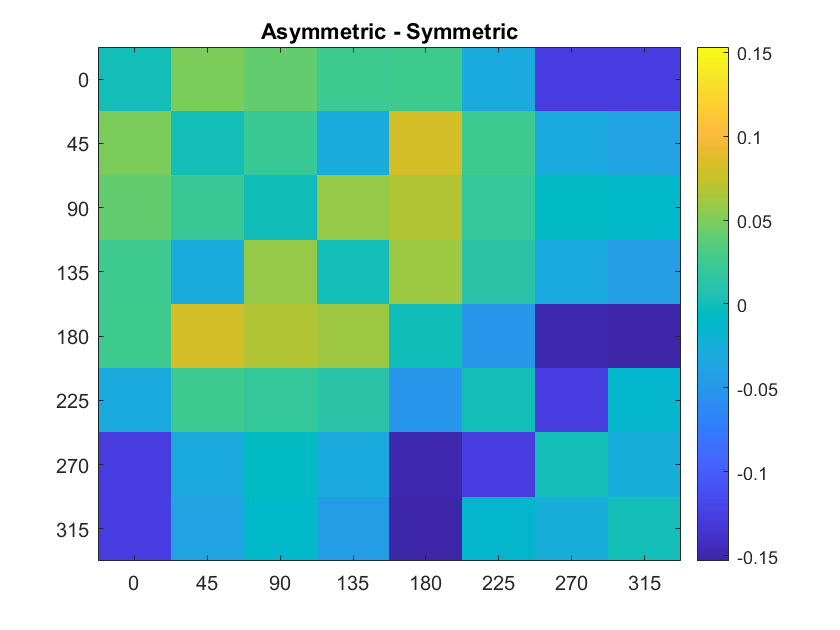

%Calculate the error between Up vs Down and Up vs Flipped Up AUCs
differenceMatrix = AUC_matrix - AUC_matrix_UPFLIPPED;

figure
imagesc(differenceMatrix)
hold on
title('Asymmetric - Symmetric')
ts = {'0', '45', '90', '135', '180', '225', '270', '315'};
xticklabels(ts)
yticklabels(ts)
colorbar
extremeVal = max(max(abs(differenceMatrix)));
caxis([-extremeVal, extremeVal])

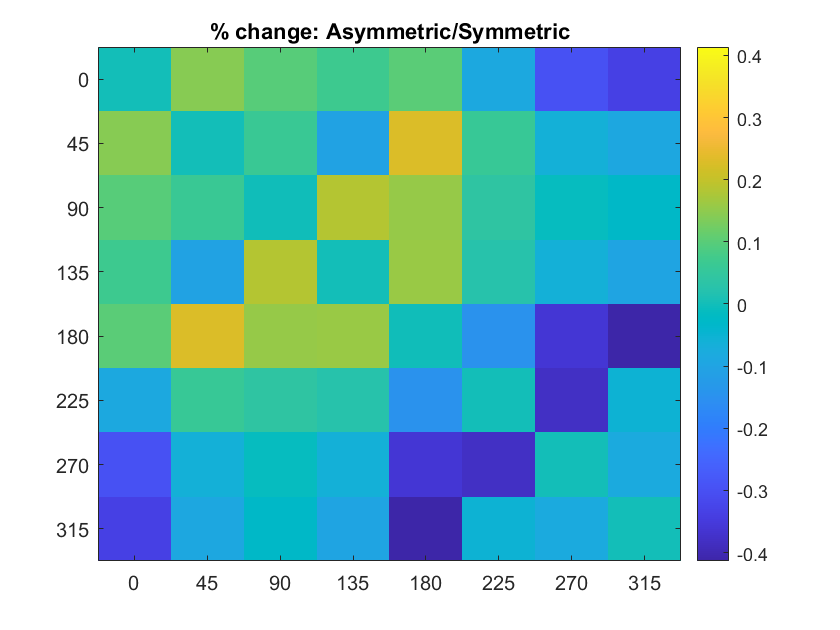

fractionMatrix = 2*(AUC_matrix./AUC_matrix_UPFLIPPED - 1); %multiply by 2 becuase AUC is restricted to a range of 0.5, not 1.0

figure
imagesc(fractionMatrix)
hold on
title('% change: Asymmetric/Symmetric')
ts = {'0', '45', '90', '135', '180', '225', '270', '315'};
xticklabels(ts)
yticklabels(ts)
extremeVal = max(max(abs(fractionMatrix)));
caxis([-extremeVal, extremeVal])
colorbar

It would appear that the observed asymmetry worsens discriminability between nearby downward stimuli (e.g.. 270 vs 225 degrees) but generally improves discriminability between nearby upward stimuli (e.g. 90 vs 135) when encoding stimuli using a subtraction method.

Correlated Noise

One advantage of simulating by drawing from CDFs is that you can easily introduce noise correlations by correlating the randomly drawn number across cell types. For example, picking the same random number for both UP and DOWN cells should force a noise correlation of 1 (or close to it). Next, I do just this to explore the influence of noise correlations on encoding using the substraction method for both symmetric and asymmetric populations.

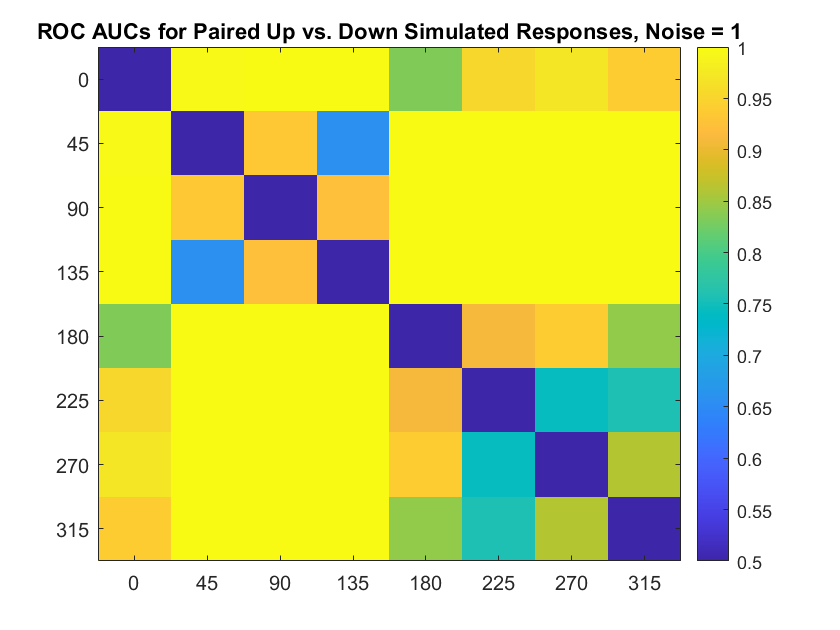

simulatedDifferences = zeros(numel(allOrientations), n);
simulatedDifferencesUPFLIPPED = zeros(numel(allOrientations), n);
for i = 1:numel(allOrientations)
    simulationDirection_i = allOrientations(i); 
    cdfUp = upDistributionFits(i, :);
    cdfDown = downDistributionFits(i, :);
    cdfUp_FLIPPED = upDistributionFits_FLIPPED(i, :);

    
    upSeeds = rand(1, n);
    downSeeds = upSeeds; %perfectly correlated noise
    upFLIPPEDSeeds = upSeeds;
    
    upResponses = zeros(1, n);
    downResponses = zeros(1, n);
    upFLIPPEDResponses = zeros(1, n);
    for run = 1:n
        [~, indxUp] = min((cdfUp - upSeeds(run)).^2);
        [~, indxDown] = min((cdfDown - downSeeds(run)).^2);
        [~, indxUpFLIPPED] = min((cdfUp_FLIPPED - upFLIPPEDSeeds(run)).^2);
        
        upResponses(run) = xFills(indxUp);
        downResponses(run) = xFills(indxDown);
        upFLIPPEDResponses (run) = xFills(indxUpFLIPPED);
    end
    simulatedDifferences(i, :) = upResponses - downResponses;
    simulatedDifferencesUPFLIPPED(i, :) = upResponses - upFLIPPEDResponses;
end

%build discriminability matrix
AUC_matrix_perfectCorrelation = zeros(numel(allOrientations));
for i = 1:numel(allOrientations)
    distribution_1 = simulatedDifferences(i, :);
    for j = 1:numel(allOrientations)
        distribution_2 = simulatedDifferences(j, :);
        
        labels =  [zeros(1, numel(distribution_1)), ones(1, numel(distribution_2))];
        scores = [distribution_1, distribution_2];
        [~, ~, ~, AUC] = perfcurve(labels, scores, 1);
        AUCNorm = max([AUC, 1-AUC]);
        
        AUC_matrix_perfectCorrelation(i, j) = AUCNorm;
    end
end

figure
imagesc(AUC_matrix_perfectCorrelation)
hold on
title('ROC AUCs for Paired Up vs. Down Simulated Responses, Noise = 1')
ts = {'0', '45', '90', '135', '180', '225', '270', '315'};
xticklabels(ts)
yticklabels(ts)
colorbar()
caxis([0.5 1])

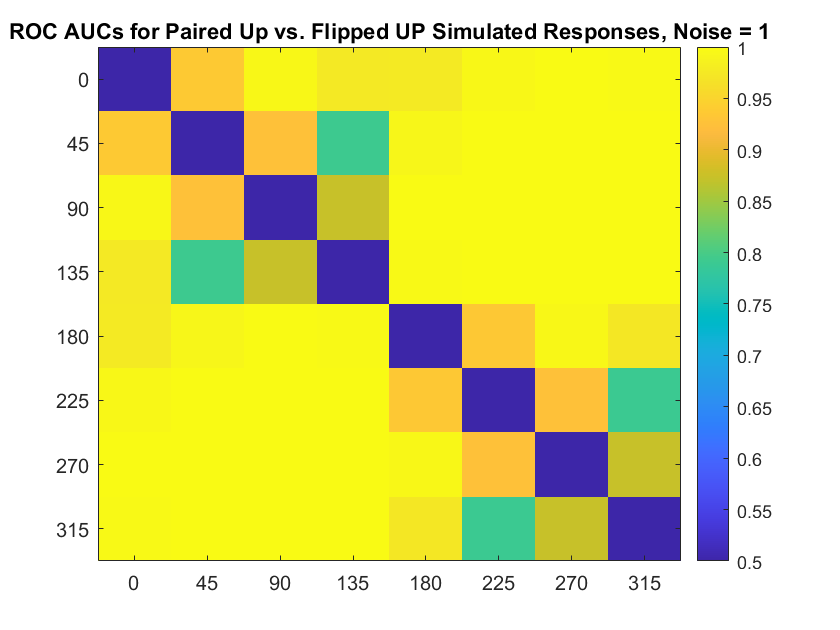

%build discriminability matrix
AUC_matrix_perfectCorrelationFLIPPED = zeros(numel(allOrientations));
for i = 1:numel(allOrientations)
    distribution_1 = simulatedDifferencesUPFLIPPED(i, :);
    for j = 1:numel(allOrientations)
        distribution_2 = simulatedDifferencesUPFLIPPED(j, :);
        
        labels =  [zeros(1, numel(distribution_1)), ones(1, numel(distribution_2))];
        scores = [distribution_1, distribution_2];
        [~, ~, ~, AUC] = perfcurve(labels, scores, 1);
        AUCNorm = max([AUC, 1-AUC]);
        
        AUC_matrix_perfectCorrelationFLIPPED(i, j) = AUCNorm;
    end
end

figure
imagesc(AUC_matrix_perfectCorrelationFLIPPED)
hold on
title('ROC AUCs for Paired Up vs. Flipped UP Simulated Responses, Noise = 1')
ts = {'0', '45', '90', '135', '180', '225', '270', '315'};
xticklabels(ts)
yticklabels(ts)
colorbar()
caxis([0.5 1])

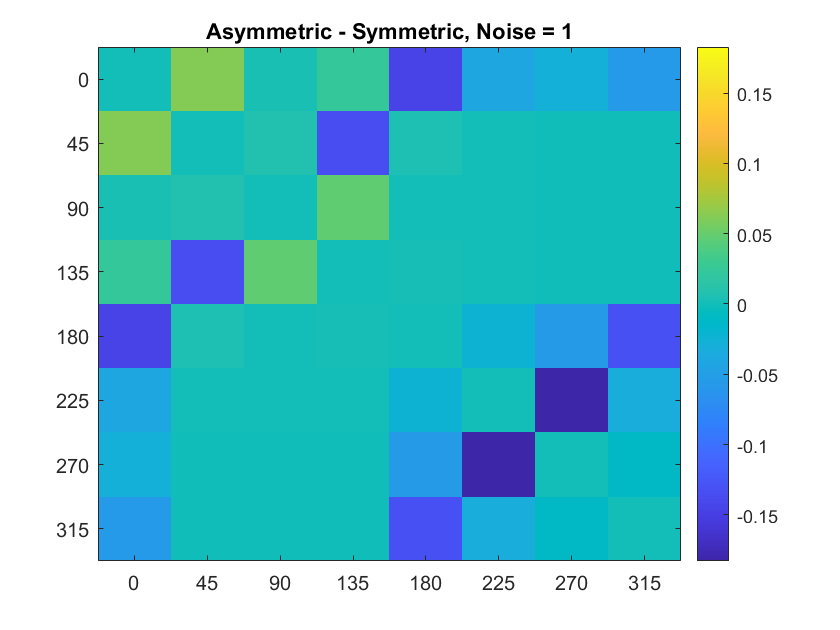

differenceMatrix_perfectCorrelation = AUC_matrix_perfectCorrelation - AUC_matrix_perfectCorrelationFLIPPED;

figure
imagesc(differenceMatrix_perfectCorrelation)
hold on
title('Asymmetric - Symmetric, Noise = 1')
ts = {'0', '45', '90', '135', '180', '225', '270', '315'};
xticklabels(ts)
yticklabels(ts)
colorbar
extremeVal = max(max(abs(differenceMatrix_perfectCorrelation)));
caxis([-extremeVal, extremeVal])